# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.1003   -0.0915   -0.0830   -0.1076   -0.0946   -0.1004   -0.1016   -0.1000   -0.0998   -0.1002   -0.1001   -0.1002   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003   -0.1003
   -0.0185   -0.0754    0.0094   -0.0326   -0.0133   -0.0163   -0.0195   -0.0200   -0.0184   -0.0186   -0.0185   -0.0186   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0.0185   -0

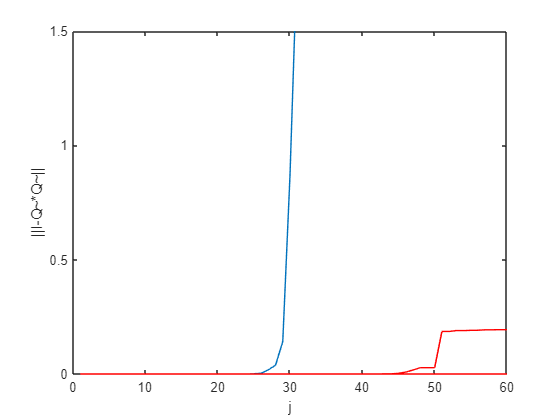


% Oefening 4
e1 = zeros(n);
e2 = zeros(n);

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest') % fout is exponentieel ma geen idee waarom

% Oefening 8
orth1 = zeros(n);
orth2 = zeros(n);

for j = 1:n
    orth1(j) = norm(eye(j) - transpose(Q1(:,1:j))*Q1(:,1:j));
    orth2(j) = norm(eye(j) - transpose(Q2(:,1:j))*Q2(:,1:j));
end

plot(orth1)
hold on
plot(orth2,'Color','r')
hold off
xlabel('j')
ylabel('||I-Q~*Q~||')
axis([0 60 0 1.5])

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.1474   -0.0937   -0.1421
   -0.0276   -0.0810   -0.0243
   -0.0147   -0.0893   -0.0293
    0.0268    0.0643    0.0210
   -0.0082    0.0511   -0.0224
   -0.1273   -0.1355   -0.1404
    0.0680    0.0469    0.0268
   -0.0692   -0.0543   -0.0786
    0.0503    0.0955    0.0125
   -0.1522   -0.1495   -0.1485


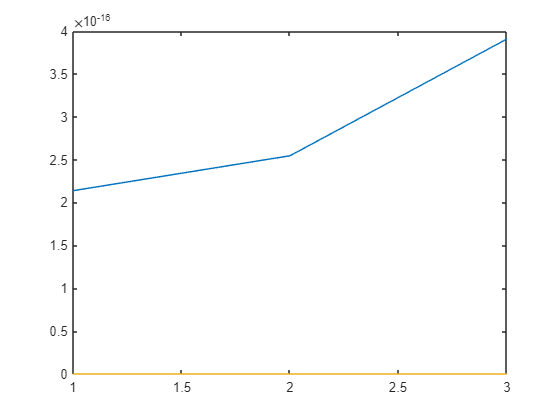

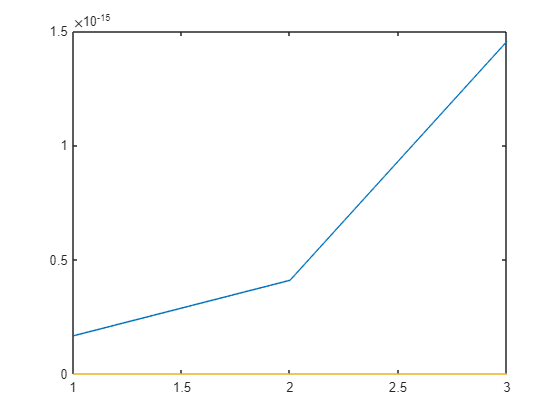


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

% Oefening 9
m = 200;
n = 50;
k = 1:50

k =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



B = randn(m,n);
[Q,~] = qr(B,0)

Q =    -0.0242   -0.0840   -0.0572   -0.0627   -0.0946   -0.0606   -0.0394    0.0173   -0.0469    0.0243    0.0003   -0.0054    0.1174    0.0824   -0.0506    0.0071   -0.0680   -0.0025   -0.0738   -0.0363   -0.0502    0.0895   -0.0792   -0.0191    0.1611    0.0782    0.0623   -0.0888   -0.1184   -0.1605    0.0309   -0.0287   -0.0014    0.0004   -0.0382   -0.0245   -0.1015   -0.1084   -0.1299   -0.0025   -0.0492   -0.0684    0.0522   -0.0823    0.0126    0.0204   -0.0677    0.1008    0.1145    0.0227
    0.1224   -0.0739    0.0093    0.0214   -0.0296   -0.1429   -0.0240    0.0760    0.1051   -0.0207   -0.0428   -0.0663   -0.0412    0.0673    0.0264    0.0013   -0.1089    0.0191    0.0605   -0.0069   -0.0447    0.0539   -0.0295    0.0104    0.0220   -0.0378    0.0171   -0.0261   -0.0529   -0.0483    0.0674   -0.0201   -0.0787    0.1085   -0.0199    0.0182   -0.0022   -0.0159    0.1861    0.0743    0.0750    0.1753   -0.0340    0.0607   -0.0334   -0.0788   -0.0212    0.0449   -0.0155    0


V = randn(n) % change this to orthogonal matrix

V =     1.0199    0.7374   -0.2879   -0.3541   -0.1560    0.2054    1.0719    1.5448    1.5377   -0.5159   -0.0456    0.4001    1.6544    1.8447   -0.4188   -0.1638   -0.1706   -0.3181    0.1618    0.1634   -1.1730    1.5240    1.0432   -0.3348    1.3954   -0.6971    0.7886    0.9636    1.7572   -2.1721   -1.7532   -0.4511    0.2678   -0.1340   -0.7994    0.5417    1.7621    0.4925    1.0540    0.1666    0.1609    0.1089   -2.1912   -0.1759   -1.0375   -1.2620    0.9131   -0.3155    2.5200   -0.7588
    0.1804    1.0355    0.4442   -0.4172   -0.9079   -0.6010   -0.8221    0.0524   -0.9129    0.2774   -1.1091    0.0289    0.8984   -1.7610    0.5983    0.9519   -0.9557   -2.0028    0.6487    1.4639   -0.9123    0.5691   -0.7361    0.4067   -0.6526    1.3231   -1.5676   -0.0474   -0.4065   -2.2735    0.1480    0.9234    0.3467   -1.9368   -0.0519    0.3934   -0.5696   -0.1078   -0.5070    1.0200    1.0590   -0.5741    0.8000   -1.0065    0.6534   -1.6853    1.1127    2.4169    1.0585    0


D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D

D = D(:,:,1) =

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   


A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A

A = A(:,:,1) =

   -0.2545   -0.5941   -0.3921    0.7328    0.0602    0.1967   -0.5102   -0.3230   -0.1261    0.6029    0.1600   -1.5765    0.3448    0.5036    0.6985   -0.4058    0.8563   -0.1586   -0.1038   -1.3442   -0.2666   -0.5405    0.5621    0.6335    0.9128    0.1757    0.7467    0.3990    0.6336    0.5560   -0.3614   -0.5996   -1.4892    0.6824    0.2524   -0.5362   -0.3839   -0.5012   -1.2559    1.1539    0.9025   -0.1798   -0.5816    0.9384    0.1578    0.0578    0.1089   -0.1040    0.3444    0.0974
    1.4719   -0.0258    0.7718   -0.5901    0.1150    0.2242    0.6992   -0.4314    0.5939   -0.0020    0.7339    0.1907    0.5155    1.1577   -0.7732   -0.1034   -0.5302   -0.5308    0.0381   -0.0965   -1.4598    0.4075    0.4012    0.1401    0.1370   -0.3229    1.8300    1.0104    1.6978   -1.3271    1.0033    0.6963   -0.8890    0.5521   -0.3754   -0.2972    0.5112   -0.1841    0.6104   -0.1784    0.5830    0.0642    0.1313   -0.5382    0.3225   -1.2466   -0.7301    0.0351   


K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



% Oefening 10
Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1

Q1 = Q1(:,:,1) =

   -0.0226   -0.0623   -0.0383    0.0741   -0.0218    0.0076   -0.1025   -0.0449    0.0097    0.0434   -0.0110   -0.1570    0.0587    0.0599    0.0580   -0.0378    0.1199   -0.0561    0.0009   -0.1152   -0.0697   -0.0310   -0.0408    0.0111    0.0830    0.0283    0.0739    0.0939   -0.0449    0.0665   -0.0894   -0.0001   -0.1232   -0.0141   -0.0530    0.0675   -0.0629    0.1072   -0.0655    0.1604   -0.0492    0.0032   -0.0948    0.0816   -0.0726    0.0442   -0.0457    0.1183    0.0919   -0.0032
    0.1304    0.0018    0.0935   -0.0477    0.0150    0.0273    0.1080   -0.0039    0.0443   -0.0316    0.1087   -0.0165    0.0262    0.1366   -0.0514    0.0156   -0.1023   -0.0667   -0.1054   -0.0984   -0.0849   -0.0203    0.0388   -0.0836    0.0343   -0.0364    0.0834    0.0328    0.1168   -0.0489    0.0720    0.0196   -0.0308   -0.0139   -0.1409    0.0929    0.0397   -0.0970    0.0424    0.0676    0.0002    0.0045    0.0538   -0.0750   -0.0329    0.0505   -0.0044    0.0541 


Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2

Q2 = Q2(:,:,1) =

   -0.0226   -0.0623   -0.0383    0.0741   -0.0218    0.0076   -0.1025   -0.0449    0.0097    0.0434   -0.0110   -0.1570    0.0587    0.0599    0.0580   -0.0378    0.1199   -0.0561    0.0009   -0.1152   -0.0697   -0.0310   -0.0408    0.0111    0.0830    0.0283    0.0739    0.0939   -0.0449    0.0665   -0.0894   -0.0001   -0.1232   -0.0141   -0.0530    0.0675   -0.0629    0.1072   -0.0655    0.1604   -0.0492    0.0032   -0.0948    0.0816   -0.0726    0.0442   -0.0457    0.1183    0.0919   -0.0032
    0.1304    0.0018    0.0935   -0.0477    0.0150    0.0273    0.1080   -0.0039    0.0443   -0.0316    0.1087   -0.0165    0.0262    0.1366   -0.0514    0.0156   -0.1023   -0.0667   -0.1054   -0.0984   -0.0849   -0.0203    0.0388   -0.0836    0.0343   -0.0364    0.0834    0.0328    0.1168   -0.0489    0.0720    0.0196   -0.0308   -0.0139   -0.1409    0.0929    0.0397   -0.0970    0.0424    0.0676    0.0002    0.0045    0.0538   -0.0750   -0.0329    0.0505   -0.0044    0.0541 


Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3

Q3 = Q3(:,:,1) =

   -0.0226   -0.0631   -0.0381    0.0803   -0.0434   -0.0019   -0.1363   -0.0461    0.0470    0.0214   -0.0844   -0.0302    0.1089   -0.0771   -0.0686   -0.1047    0.1641   -0.0280    0.1036    0.0737   -0.0985    0.0966   -0.0675    0.0887   -0.0834    0.0086    0.1285    0.1076   -0.0632   -0.0723    0.0835    0.1332    0.0909   -0.1025   -0.0724   -0.0867    0.0767    0.0418   -0.0549   -0.0795   -0.1068    0.1203    0.0885   -0.0676    0.0983   -0.1039   -0.1021    0.0752    0.0370   -0.1232
    0.1304    0.0062    0.1097   -0.0396    0.0130    0.0343    0.1218    0.0429    0.0204   -0.0415    0.1307   -0.0616   -0.0403    0.1412    0.0824    0.0747   -0.1397   -0.0335   -0.1283   -0.1242    0.0326   -0.1174    0.1468   -0.0995    0.1253   -0.0676   -0.1073   -0.0421    0.1163    0.0880   -0.0792   -0.1237   -0.1294    0.1247    0.1064    0.1073   -0.1005   -0.1077    0.0730    0.1199    0.1281   -0.1390   -0.1141    0.0949   -0.1079    0.1144    0.1276   -0.1020 


orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i).'*Q1(:,:,i));
end
orth1

orth1 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i).'*Q2(:,:,i));
end
orth2

orth2 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i).'*Q3(:,:,i));
end
orth3

orth3 =    30.9989
   26.9467
   34.3473
   35.5448
   36.1005
   35.6032
   42.1512
   43.2605
   43.8637
   42.0156


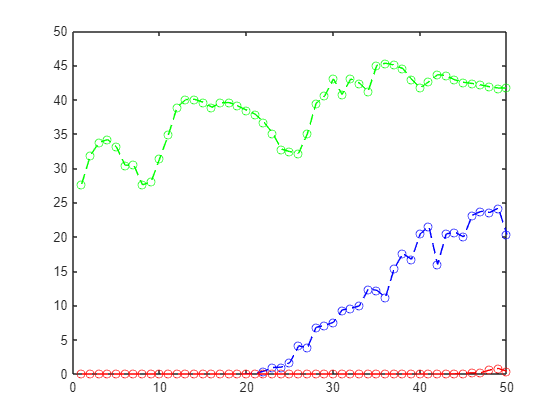


plot(k, orth1, 'b--o', k, orth2, 'r--o', k, orth3, 'g--o')


%Fout is veel te groot voor KLGS en herGS, kan niet!

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

[V,H] = Arnoldi(A,v,m);

